clc
clear
close all


airfoils_vec = {"NACA 0012", "NACA 2412", "MH78"};
MR = [10 20 50 75 100];% 125 150 250];

cc = {"ko-", "k^-", "ks-"}

cc = 1×3 cell array
    {["ko-"]}    {["k^-"]}    {["ks-"]}



data = load("multiple_sims_results_MR.mat")

data = struct with fields:
    f_max: [3×8 double]
      rpm: [3×8 double]
        t: [3×8 double]
    t_max: [3×8 double]
        v: [3×8 double]


erros = (data.v(:, :) + 29.4549218847750)/(-29.4549218847750)

erros =    -0.5209   -0.3608   -0.0230    0.1900    0.3658    0.5179    0.6456    0.8905
   -0.6491   -0.5257   -0.2663   -0.1018    0.0396    0.1629   -0.4442   -0.2776
   -0.5675   -0.4215   -0.1111    0.0892    0.2587    0.4059    0.5328    0.0012


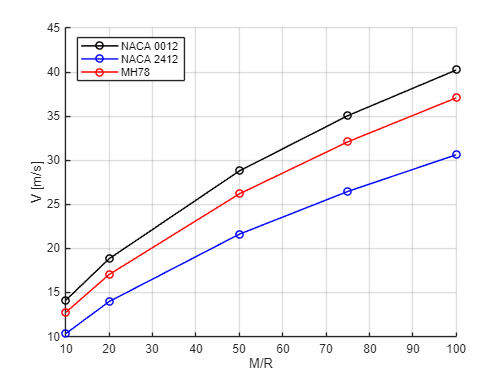


figure()
hold on
plot(MR, -data.v(1, 1:5), 'ko-', 'LineWidth', 1.2, "DisplayName", airfoils_vec{1})
plot(MR, -data.v(2, 1:5), 'bo-', 'LineWidth', 1.2, "DisplayName", airfoils_vec{2})
plot(MR, -data.v(3, 1:5), 'ro-', 'LineWidth', 1.2, "DisplayName", airfoils_vec{3})
grid on
xlabel("M/R")
ylabel("V [m/s]")
legend("Location","best")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'vel_rm_comp', '-depsc')  % EPS a cores

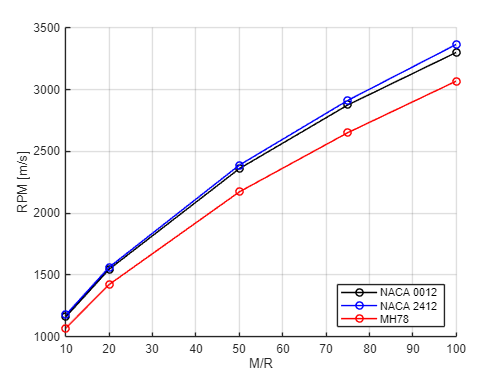

figure()
hold on
plot(MR, data.rpm(1, 1:5) * 60 / (2*pi), 'ko-', 'LineWidth', 1.2, "DisplayName", airfoils_vec{1})
plot(MR, data.rpm(2, 1:5)* 60 / (2*pi), 'bo-', 'LineWidth', 1.2, "DisplayName", airfoils_vec{2})
plot(MR, data.rpm(3, 1:5)* 60 / (2*pi), 'ro-', 'LineWidth', 1.2, "DisplayName", airfoils_vec{3})
grid on
xlabel("M/R")
ylabel("RPM [m/s]")
legend("Location","best")
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'rpm_rm_comp', '-depsc')  % EPS a cores